#  Integración por partes 

[Potencias y logaritmos](matlab:open('MainMenu.mlx'))

 La integración por partes es un método de integración extremadamente poderoso que solo se enfocará por completo una vez que lo apliques a la resolución de ecuaciones diferenciales. Por el momento, sin embargo, te permitirá resolver algunas integrales con las que la sustitución no ayuda. 

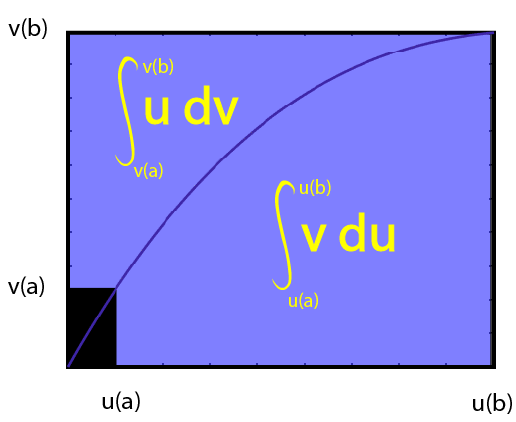

 La integración por partes le permite subdividir su integrando en componentes integrados y diferenciados y recombinar esas piezas de maneras que puedan ser más fáciles de calcular. 

** Antes de comenzar: **

 Este script en vivo está diseñado para usarse con el código oculto. En la pestaña ** Ver ** de la barra de herramientas de MATLAB, en la sección ** Ver **, seleccione ** Ocultar código **.  Alternativamente, seleccione ** Ocultar código ** usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesita más instrucción, considere realizar [Documentación de MATLAB sobre cosint](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB. 

 Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se agotan. 

##  Integración por partes geométricamente 

 Considere la relación dada por la regla del producto para derivadas: 


$$\frac{d}{dt}\left[u(t)\cdot v(t)\right] = u(t)\cdot \frac{dv}{dt} + \frac{du}{dt}\cdot v(t).\;\;\;\;\;\;\; (\star)$$


 Aplicando [Identificación de componentes integrables y diferenciables.](matlab:open('./FundamentalTheorem.mlx')) y linealidad, podemos ver que 


$$\int_a^b \frac{d}{dt}\left[u(t)\cdot v(t)\right] \; dt = \int_a^b u(t)\cdot \frac{dv}{dt} \; dt + \int_a^b \frac{du}{dt}\cdot v(t)\; dt \;\;\;\;\;\;\; (1)$$
   


$$u(b)v(b)-u(a)v(a) = \int_{a}^{b}u(t)\cdot\frac{dv}{dt}\;dt + \int_{a}^{b}v(t)\cdot \frac{du}{dt}\;dt \;\;\;\;\;\;\; (2)$$
   

 Para entender la geometría, vamos a ver, expresemos la ecuación (2) de una manera ligeramente diferente. Observe que 


$$\frac{dv}{dt}\; dt = \lim_{dt \to 0} \frac{v(t+dt)-v(t)}{dt}\cdot dt = \lim_{dt \to 0} v(t+dt)-v(t) = dv,$$


 donde $dv$ es el cambio en el valor de $v$ a medida que ese cambio se acerca a $0$. Si además notamos que, donde las funciones son invertibles, podemos escribir $u(v)$ y $v(u)$ , esto significa que podríamos decir: 


$$u(b)v(b)-u(a)v(a) = \int_{v(a)}^{v(b)}u(v)\;dv + \int_{u(a)}^{u(b)}v(u)\; du \;\;\;\;\;\;\; (3)$$


El lado izquierdo de la ecuación $(3)$ es la diferencia de los dos rectángulos mientras que el lado derecho El lado de la ecuación $(3)$ subdivide la misma región en una suma de dos partes divididas por la curva $(u,v)$. En la práctica, expresar $u$ como una función de $v$ o viceversa puede ser complejo algebraicamente, pero es sencillo geométricamente usando la parametrización en términos de $t$ : 

figure
syms t
u(t) = t^2;
v(t) = 1-cos(t);
 
tl = tiledlayout(1,2); %#ok<NASGU> 
tVals = -5:.01:5;
uVals = u(tVals);
vVals = v(tVals);
nexttile
plot(uVals,vVals)
title("Plotting $v$ against $u$","Interpreter","latex")
xlabel("$u(t)$","Interpreter","latex")
ylabel("$v(t)$","Interpreter","latex")
axis square
nexttile
plot(vVals,uVals)
title("Plotting $u$ against $v$","Interpreter","latex")
xlabel("$v(t)$","Interpreter","latex")
ylabel("$u(t)$","Interpreter","latex")
axis square
% Add layout title
% title(tl,"Thinking in Curves: Two Rotations/Reflections of $u$ and $v$","Interpreter","latex")
% subtitle(tl,"$t \in [-5,5]$","Interpreter","latex")

 En muchos casos, incluso con $u(t) = t^2$ y $v(t) = 1-\cos(t)$ , uno o más de los gráficos resultantes no son funciones. Sin embargo, una restricción suficiente del dominio dará como resultado una relación funcional para cualquier función parametrizada suficientemente agradable $u(t)$ y $v(t)$. 

  ** Pruebe **. ¿Puede restringir el dominio de $t=a$ a $t=b$ de modo que tanto $u(v)$ como $v(u)$ sean funciones $1:1$ sobre ese dominio? 

figure
syms t
u(t) = t^2;
v(t) = 1-cos(t);
a = -5;
b = 5;
 
tl = tiledlayout(1,2);
if a < b
    tVals = a:.01:b;
else
    warning("You should choose a < b.")
    tVals = b:.01:a;
end
uVals = u(tVals);
vVals = v(tVals);
nexttile
plot(uVals,vVals)
title("Plotting $v$ as a function of $u$","Interpreter","latex")
xlabel("$u(t)$","Interpreter","latex")
ylabel("$v(t)$","Interpreter","latex")
axis square
nexttile
plot(vVals,uVals)
title("Plotting $u$ as a function of $v$","Interpreter","latex")
xlabel("$v(t)$","Interpreter","latex")
ylabel("$u(t)$","Interpreter","latex")
axis square
% Add layout title
% title(tl,"Thinking in Curves: Two Rotations/Reflections of $u$ and $v$","Interpreter","latex")
% subtitle(tl,"$t \in ["+a+","+b+"]$","Interpreter","latex")

  ** Pruebe **. 

figure
syms t
u(t) = t^2;
v(t) = 1-cos(t);
a = 1;
b = 3;
 
if a>b
    disp("This code requires that b>a. Your endpoints have been reversed.")
    ar = b;
    br = a;
else
    ar = a;
    br = b;
end
tVals = ar:.01:br;
numSteps = length(tVals);
uVals = u(tVals);
vVals = v(tVals);
z = zeros(size(tVals));
p = plot(uVals,vVals);
title("Geometric Integration by Parts")
hold on
xlabel("u(t)")
ylabel("v(t)")
v0 = double(v(0));
u0 = double(u(0));
[hx,hy,dUPosRegions,dUNegRegions,dULines] = PlotRegions(vVals,uVals,v0,["r" "b"],"h");
[vx,vy,dVPosRegions,dVNegRegions,dVLines] = PlotRegions(uVals,vVals,u0,["r" "b"],"v");
rectGrp = DrawRectangles(uVals,vVals,u0,v0);
surface([uVals;uVals],[vVals;vVals],[z;z],[tVals;tVals],...
    "FaceColor","none","EdgeColor","interp","LineWidth",2)
hold off
SetXTicks(p.Parent,double([u(ar) u(br)]),["u(a)" "u(b)"])
SetYTicks(p.Parent,double([v(ar) v(br)]),["v(a)" "v(b)"]) 

showPosdUReg = true; showNegdUReg = true;
showPosdVReg = false; showNegdVReg = false;
showRectSubs = true; hideVertStripes = false;    hideHorizStripes = true;
if showPosdUReg
    dUPosRegions.Visible = "on";
else
    dUPosRegions.Visible = "off"; %#ok<*UNRCH> 
end
if showNegdUReg
    dUNegRegions.Visible = "on";
else
    dUNegRegions.Visible = "off";
end
if showPosdVReg
    dVPosRegions.Visible = "on";
else
    dVPosRegions.Visible = "off";
end
if showNegdVReg
    dVNegRegions.Visible = "on";
else
    dVNegRegions.Visible = "off";
end
if hideVertStripes
    dULines.Visible = "off";
else
    dULines.Visible = "on";
end
if hideHorizStripes 
    dVLines.Visible = "off";
else
    dVLines.Visible = "on";
end
if showRectSubs
    rectGrp.Visible = "on";
else
    rectGrp.Visible = "off";
end

  ** Pruebe **. 

-  ¿Qué sucede si mantiene los valores predeterminados de $u(t) = t$ y $v(t) = 1-\cos(t)$ pero cambia el dominio de integración de $a = 0$ a $b=3$ para que sea $a=0$ a $b=5$? 

-  ¿Qué pasa si usas $u(t) = t^2$ y $v(t) = \sin^2(t)$ con $a=0$ a $b=3$ ? 

-  ¿Qué pasa si usas $u(t) = e^t$ y $v(t) = t$ con cualquier valor de $a$ y $b$ ? 

-  ¿Qué pasa si usas $u(t) = e^t$ y $v(t) = t^2$ con $a=0$ y $b=5$ ? ¿O $a=-3$ y $b=3$? 

##  Integración algebraica por partes 

 Comenzando con la regla del producto para derivadas en Rampa de entrada de MATLAB(\star) y reordenando las partes, tenemos: 


$$u(t)\cdot \frac{dv}{dt} = \frac{d}{dt}\left[u(t)\cdot v(t)\right] - \frac{du}{dt}\cdot v(t) .$$


 Integrando, esto se convierte en 


$$\int u(t)\cdot \frac{dv}{dt}\; dt = \int \frac{d}{dt}\left[u(t)\cdot v(t)\right] - \frac{du}{dt}\cdot v(t)\; dt$$



$$\int u(t)\cdot \frac{dv}{dt}\; dt = \int \frac{d}{dt}\left[u(t)\cdot v(t)\right]\; dt - \int v(t) \frac{du}{dt}\; dt$$



$$\int u(t)\cdot \frac{dv}{dt}\; dt = u(t)\cdot v(t) - \int v(t) \frac{du}{dt}\; dt \;\;\;\;\;\;\; (\diamond)$$


 Esto frecuentemente se abrevia a $\int u\; dv = uv-\int v\; du$. Esto es importante porque nos permite reemplazar componentes que quizás no sepamos cómo integrar (como $u(t)$ ) con términos con los que puede ser más fácil trabajar (como $\frac{du}{dt}$ ). Esto requiere que la parte restante del integrando, expresada aquí como $\frac{dv}{dt}$, sea una función integrable. 

##  Identificar componentes integrables y diferenciables 

###  Potencias y logaritmos 

 Cuando hay un logaritmo natural en un integrando que no existe como parte de una sustitución, el único método exacto disponible es usar la integración por partes con el logaritmo natural como $u$ en la ecuación $(\diamond)$. 

** Ejemplo: ** $\int t^{3/4}\ln(t)\; dt$

 Dejemos que $u(t) = \ln(t)$ luego $\frac{dv}{dt} = t^{3/4}$. Esto significa que 


$$\frac{du}{dt} = \frac{d}{dt}\left[\ln(t)\right] = \frac{1}{t}$$
 

 y 


$$v(t) = \int \frac{dv}{dt}\; dt = \int t^{3/4}\; dt = \frac{4}{7}t^{7/4}.$$


 Al juntar todas estas piezas en la ecuación $(\diamond)$ , tenemos 


$$\int t^{3/4}\ln(t)\; dt = \ln(t)\cdot \frac{4}{7}t^{7/4}-\int \frac{4}{7}t^{7/4}\cdot \frac{1}{t}\; dt$$
 

 que se evalúa como 


$$\int t^{3/4}\ln(t)\; dt = \frac{4}{7}t^{7/4}\ln(t) - \frac{4}{7}\int t^{3/4}\; dt$$


                        
$$= \frac{4}{7}t^{7/4}\ln(t)-\frac{16}{49}t^{7/4}+C$$


                     
$$= \frac{4}{7}t^{7/4}\left(\ln(t)-\frac{4}{7}\right)+C$$


####  Practice 

  ** Pro-tip **. La sintaxis de MATLAB es 7 `*t^(2/3)` para $7t^{2/3}$. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. 

if ~exist("varOpts","var")
    syms t r x z C                       %#ok<NASGU> % Declarar variables simbólicas
    varOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
end
    [myFun,varChoice] = GenProbType(varOpts,3);  % genProbType está definido en Funciones auxiliares
    % genProbType configura una variable y genera una función aleatoria
    
                                   % Run this section 

myAnswer = r;     % Solución definida por el usuario, valor predeterminado r
assume(varChoice>0)
Check1(myFun,varChoice,myAnswer);
                          % Run this section

###  Polinomios y Cosenos, Senos o Exponenciales 

 Si integramos senos y/o cosenos, encontramos cosenos y/o senos. Si integramos exponenciales, nos encontramos con múltiplos del mismo exponencial restante. Esto significa que si elegimos $\frac{dv}{dt}$ para incluir senos, cosenos o exponenciales, el $v$ resultante no será más difícil de integrar que el original, aunque tampoco será más sencillo. Sin embargo, si este término repetidamente integrable se multiplica por un polinomio de $n^{\text{th}}$ grados, entonces con $n$ aplicaciones de integración por partes el término polinómico desaparecerá dejando solo la función integrable. 

** Ejemplo: **$\int (x^2-3x+7)\cos(4x)\; dx$

 Aplique la ecuación $(\diamond)$ con $\frac{dv}{dx} = \cos(4x)$ y $u = x^2-3x+7$ para que tengamos $v = -\frac{1}{4}\sin(4x)$ y $\frac{du}{dx} = 2x-3$. Recombinando en la primera integración por partes tenemos: 


$$\int (x^2-3x+7)\cos(4x)\; dx = -\frac{(x^2-3x+7)}{4}\sin(4x)+\frac{1}{4}\int (2x-3)\sin(4x)\; dx$$


 Repitiendo este procedimiento, tenemos $\frac{dv}{dx} = \sin(4x)$ y $u(x) = 2x-3$ entonces $v = -\frac{1}{4}\cos(4x)$ y $\frac{du}{dx} = 2$. Recombinando en la ecuación $(\diamond)$ tenemos: 


$$\int (x^2-3x+7)\cos(4x)\; dx = -\frac{(x^2-3x+7)}{4}\sin(4x)+\frac{1}{4}\left[\frac{(3-2x)}{4}\cos(4x)+\frac{1}{2}\int\cos(4x)\; dx\right]$$


                                   
$$= -\frac{(x^2-3x+7)}{4}\sin(4x)+\frac{(3-2x)}{16}\cos(4x)+\frac{1}{32}\sin(4x)+C$$


####  Práctica 

if ~exist("varOpts","var")
    syms t r x z C                       %#ok<NASGU> % Declarar variables simbólicas
    varOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
end
    [myFun,varChoice] = GenProbType(varOpts,2);  % genProbType está definido en Funciones auxiliares
    % genProbType configura una variable y genera una función aleatoria
    
                                   % Run this section 

myAnswer = r;     % Solución definida por el usuario, valor predeterminado r
assume(varChoice>0)
Check1(myFun,varChoice,myAnswer);
                          % Run this section

###  Cosenos, senos y exponenciales 

 Si estás intentando integrar un producto de senos, cosenos o exponenciales, entonces puedes elegir cualquiera de los componentes para que sea $u$ o $v$ , pero deberás prestar mucha atención a la forma de tu integral en cada paso. Estas integrales se resuelven utilizando tanto álgebra como integración por partes. 

** Ejemplo: **$\int  \cos(4t-3)e^{-7t}\; dt$

 Sea $u = \cos(4t-3)$ y $\frac{dv}{dt} = e^{-7t}$. Luego $\frac{du}{dt} = -4\sin(4t-3)$ y $v = -\frac{1}{7}e^{-7t}$. Por lo tanto, 


$$\int \cos(4t-3)e^{-7t}\; dt = -\frac{1}{7}\cos(4t-3)e^{-7t}-\frac{4}{7}\int\sin(4t-3)e^{-7t}\; dt.$$
 

 Aplicando la ecuación $(\diamond)$ nuevamente con $u = \sin(4t-3)$ y $\frac{dv}{dt} = e^{-7t}$, entonces $\frac{du}{dt} = 4\cos(4t-3)$ y $v = -\frac{1}{7}e^{-7t}$ tenemos 

        
$$\int \cos(4t-3)e^{-7t}\; dt = -\frac{1}{7}\cos(4t-3)e^{-7t}-\frac{4}{7}\left[-\frac{1}{7}\sin(4t-3)e^{-7t}+\frac{4}{7}\int \cos(4t-3)e^{-7t}\; dt\right]$$


   
$$\int \cos(4t-3)e^{-7t}\; dt = -\frac{1}{7}\cos(4t-3)e^{-7t}+\frac{4}{49}\sin(4t-3)e^{-7t}-\frac{16}{49}\int \cos(4t-3)e^{-7t}\; dt$$
 

. Observe que la integral original ahora está presente en ambos lados de la ecuación. Combinándolos y simplificando, tenemos: 


$$\int \cos(4t-3)e^{-7t}\; dt + \frac{16}{49}\int \cos(4t-3)e^{-7t}\; dt = -\frac{1}{7}\cos(4t-3)e^{-7t}+\frac{4}{49}\sin(4t-3)e^{-7t}$$
                                                                                             


$$\frac{65}{49}\int \cos(4t-3)e^{-7t}\; dt = -\frac{1}{7}\cos(4t-3)e^{-7t}+\frac{4}{49}\sin(4t-3)e^{-7t}$$
                                            


$$\int \cos(4t-3)e^{-7t}\; dt = -\frac{7}{65}\cos(4t-3)e^{-7t}+\frac{4}{65}\sin(4t-3)e^{-7t} + C$$
        

####  Práctica 

if ~exist("varOpts","var")
    syms t r x z C                       %#ok<NASGU> % Declarar variables simbólicas
    varOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
end
    [myFun,varChoice] = GenProbType(varOpts,4);  % genProbType está definido en Funciones auxiliares
    % genProbType configura una variable y genera una función aleatoria
    
                                   % Run this section 

myAnswer = r;     % Solución definida por el usuario, valor predeterminado r
assume(varChoice>0)
Check1(myFun,varChoice,myAnswer);
                          % Run this section

##  La integración por partes puede generar resultados sorprendentes 

 A diferencia de otros métodos simples de integración, la integración por partes es única porque se puede aplicar a cada función integrable. El problema es que la expresión equivalente resultante puede ser útil o no para determinar el valor. 

####  Cíñete a una opción 

 Si cambias componentes entre múltiples aplicaciones de integración por partes, puedes demostrar afirmaciones verdaderas que son equivalentes a $0=0$. Si encuentra este tipo de resultado, regrese y verifique cada una de sus opciones para $u$ y $\frac{dv}{dx}$. 

** Ejemplo **$\int x^2e^x\; dx$

 Aplicar la ecuación $(\diamond)$ con $u = x^2$ y $\frac{dv}{dx} = e^x$. Luego $\frac{du}{dx} = 2x$ y $v = e^x$ , entonces 


$$\int x^2e^x\; dx = x^2e^x-2\int xe^x\; dx$$


 No hemos terminado, así que aplica la ecuación $(\diamond)$ nuevamente con $u = e^x$ y $\frac{dv}{dx} = x$ entonces $\frac{du}{dx} = e^x$ y $v = \frac{x^2}{2}$. Al ingresar estos valores tenemos 

$\int x^2e^x\; dx = x^2e^x - 2\left[e^x\left(\frac{x^2}{2}\right) - \frac{1}{2}\int x^2e^x\; dx\right].$ Simplificando, esto se convierte en 


$$\int x^2e^x\; dx = x^2e^x-e^xx^2+\int x^2e^x$$
 

 o en otras palabras, $\int x^2 e^x\; dx = \int x^2 e^x \; dx$ o $0=0$. Cierto, pero no satisfactorio si intentamos determinar el valor de la integral. Esto ocurrirá si cambia las partes del integrando que representan los componentes $u$ y $v$ en aplicaciones posteriores de la ecuación $(\diamond)$. 

####  Funciones definidas por sus integrales 

 En otros casos, las ecuaciones que descubres por integración por partes pueden relacionarse con funciones más complicadas definidas en términos de integrales. Es poco probable que los reconozca a menos que esté consultando una calculadora de integrales o sepa que se encuentra en un dominio donde es probable que ocurra una función integral especial particular. 

** Ejemplo **$\int \ln(x)\sin(x)\; dx$

 Aplicar la ecuación $(\diamond)$ con $u(x) = \ln(x)$ y $\frac{dv}{dx} = \sin(x)$. Luego tenemos 


$$\int \ln(x)\sin(x)\; dx = -\ln(x)\cos(x)+\int \frac{\cos(x)}{x}\; dx.$$


. De hecho, esto es lo mejor que podemos hacer con las herramientas disponibles. Para obtener más detalles, puede consultar el [integrales trigonométricas](https://www.mathworks.com/help/symbolic/sym.cosint.html) o la página de Wikipedia en [integral de fresnel](https://en.wikipedia.org/wiki/Trigonometric_integral). 

** Ejemplo ** $\int t^{-3/2}\cos(t)\; dt$

 Aplicar la ecuación $(\diamond)$ con $u = t^{-3/2}$ y $\frac{dv}{dt} = \cos(t)$. Luego $\frac{du}{dt} = -\frac{3}{2}t^{-5/2}$ y $v(t)= \int \cos(t)\; dt = \sin(t)$. Esto nos da 


$$\int t^{-3/2}\cos(t)\; dt = -\frac{3}{2}t^{-5/2}\sin(t) + \int \frac{3}{2}t^{-5/2}\sin(t)\; dt.$$


. Esto es cierto, pero en realidad no es útil porque la solución comprensible en términos de [Teorema fundamental del cálculo](https://www.mathworks.com/help/symbolic/sym.fresnelc.html) requiere hacer la elección opuesta con $\frac{dv}{dt} = t^{-3/2}$ y $u = \cos(t)$. 

##  Practique la integración aleatoria mediante integrales de piezas 

  ** Pro-tip **. La sintaxis de MATLAB es 7 `*t^(2/3)` para $7t^{2/3}$. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. 

% Borrar variables que pueden reutilizarse en otras partes de este módulo.
clear errorCount totIPProbs totAttempts adjustcount lastFive myFun varChoice
syms t r x z C                       % Declarar variables simbólicas
varOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
errorCount = 0;                      % Inicializar un recuento de errores
totIPProbs = 0;                    % Inicializar un recuento del total de problemas intentados
totAttempts = 0;                     % Inicializar un recuento del total de soluciones ofrecidas
adjustCount = 0;                     % Conservar los recuentos si el usuario vuelve a enviar una solución
lastFive = zeros(1,5);               % Inicializar una matriz para registrar los últimos cinco resultados de la solución
 
disp("Values initialized for Integration by Parts Practice.") 

% Compruebe si la sección anterior se ha ejecutado
% Si no, proporcione una advertencia. Si es así genera un problema.
if ~exist("totIPProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [myFun,varChoice] = GenProbType(varOpts,1);  % genProbType está definido en Funciones auxiliares
    % genProbType configura una variable y genera una función aleatoria
    totIPProbs = totIPProbs+1;     % Aumentar el recuento total de problemas intentados.
end
                                   % Run this section 

myAnswer = r;     % Solución definida por el usuario, valor predeterminado r
totAttempts = totAttempts + 1;       % Recuento de actualizaciones del total de intentos de solución
[lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totIPProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive);
% resubmissionCheck is defined in Helper Functions
% resubmissionCheck records the attempt and provides appropriate feedback
                          % Run this section

 Una vez que haya completado suficiente práctica, realice un seguimiento de los resultados generales de su práctica aquí: 

 
AnalyzeResults(totIPProbs,errorCount,totAttempts,adjustCount,lastFive)

###  Aplicación de práctica 

 Puede practicar en la aplicación Calculus Flashcards. Puede iniciar la aplicación haciendo clic en la imagen a continuación. Debe configurar el tipo de problema como "Integración por partes" en la sección Integrales. La aplicación se abrirá en una nueva ventana. 

[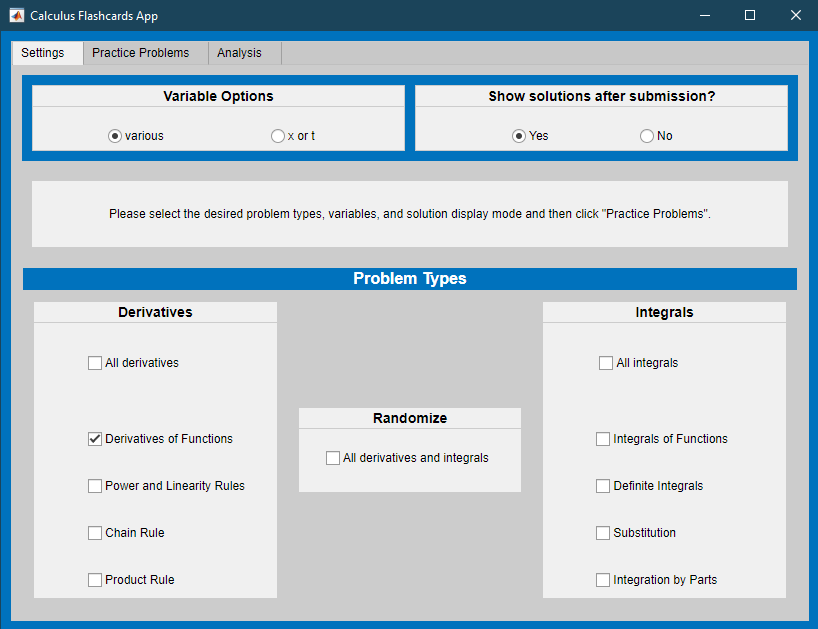](matlab: CalculusFlashcards)

 
run("CalculusFlashcards.mlapp")

[Potencias y logaritmos](matlab:open('MainMenu.mlx'))

##  Funciones auxiliares locales 

 Si desea ver los detalles del código, seleccione la pestaña ** Ver ** y cambie a ** Salida en línea **. Como alternativa, seleccione ** Salida en línea ** usando el ícono   en la parte superior derecha del panel Live Editor. 

** Crear visualizaciones de Integración por Partes **

 Trazar regiones 

function [x,y,posRegGroup,negRegGroup,LinesGroup] = PlotRegions(fVals,dVals,f0,cols,hvflag)
posRegGroup = hggroup;
negRegGroup = hggroup;
LinesGroup = hggroup;
regGrpChoice = [negRegGroup posRegGroup];
dU = double(dVals(2:end)-dVals(1:end-1));
posDU = dU >= 0;
posF = double(fVals(1:end-1))>=0;
fSignChange = posF(2:end)-posF(1:end-1);
fSignChangeIdx = find(fSignChange~=0);
dUSignChange = (posDU(2:end)-posDU(1:end-1));
dUSignChangeIdx =  find(dUSignChange~=0);
dUSignChangeIdx = [1 (dUSignChangeIdx + 1) length(dVals)];
scIdx = unique(sort([dUSignChangeIdx fSignChangeIdx]),"sorted");
scVal = (posDU(scIdx(1:end-1))==posF(scIdx(1:end-1)))+1;
alphaVal = 1/(length(scIdx)-1);
for k = 1:length(scIdx)-1
    xU = dVals(scIdx(k):scIdx(k+1)-1);
    x = double([xU flip(xU)]);
    yV = fVals(scIdx(k):scIdx(k+1)-1);
    y = double([f0*ones(size(yV)) flip(yV)]);
    if hvflag == "h"
        patch(x,y,cols(scVal(k)),"FaceAlpha",alphaVal,"Parent",regGrpChoice(scVal(k)));
        LinesGroup = AddStripes(x,y,"v",10,LinesGroup);
    else
        patch(y,x,cols(scVal(k)),"FaceAlpha",alphaVal,"Parent",regGrpChoice(scVal(k)));
        LinesGroup = AddStripes(x,y,"h",10,LinesGroup);
    end
end
end

 Agregar franjas 

function lineGroup = AddStripes(x,y,hvflag,step,lineGroup)
    % x and y are the same length, so this is just determining the bin
    % index value based on the relative sizes of the number of rectangles
    % length(x)/2 and step
    idx = DefStripes(length(x)/2,step);
    if length(idx)>1
        if hvflag == "v"       
            try
                p = plot([x(idx(1)) x(idx(1))],[y(idx(1)) y(end-idx(1))],"Parent",lineGroup,SeriesIndex="none");
            catch
                p = plot([x(idx(1)) x(idx(1))],[y(idx(1)) y(end-idx(1))],"k","Parent",lineGroup);
            end
            for k = 2:length(idx)
                copyobj(p,lineGroup)
                lineGroup.Children(k).XData = [x(idx(k)) x(idx(k))];
                lineGroup.Children(k).YData = [y(idx(k)) y(end-idx(k))];
            end
            drawnow
        else
            try
                p = plot([x(idx(1)) x(end-idx(1))],[y(idx(1)) y(idx(1))],"Parent",lineGroup,SeriesIndex="none");
            catch
                p = plot([x(idx(1)) x(end-idx(1))],[y(idx(1)) y(idx(1))],"k","Parent",lineGroup);
            end
            for k = 2:length(idx)
                copyobj(p,lineGroup)
                lineGroup.Children(k).XData = [y(idx(k)) y(end-idx(k))];
                lineGroup.Children(k).YData = [x(idx(k)) x(idx(k))];
            end
            drawnow
        end
    end
end

function idx = DefStripes(numRect,step)
    numBins = floor(numRect/step);
    if numRect > step
         rem = mod(numRect,step);
         if (rem == 0) && (numBins > 0)
             idx = 0:step:numRect;
             idx(1) = 1;
         elseif numBins >= rem
             intro = 1:(step+1):floor(rem/2)*(step+1);
             middle = floor(rem/2)*(step+1):step:(numRect-(step+1)*ceil(rem/2));
             last = (numRect-(step+1)*ceil(rem/2)):step+1:numRect;
             idx = [intro middle(2:end-1) last];
         else
            idx = 1:(ceil(rem/numBins)+step):numRect;
            if idx(end) ~= numRect
                idx = [idx numRect];
            end
         end
    else
        idx = unique([1 numRect]);
    end
end

 Dibujar rectángulos 

function rectObj = DrawRectangles(uVals,vVals,u0,v0)
rectObj = hggroup;
ua = double(uVals(1));
ub = double(uVals(end));
va = double(vVals(1));
vb = double(vVals(end));
ax = gca;
col = colormap;
fgcol = round(ax.Parent.Color); % color de la figura principal fijado en blanco/negro
bkcol = round(ax.GridColor); % color de acento fijado en blanco y negro
if (ua>u0)~=(va>v0)
    fCol = fgcol;
else
    fCol = bkcol;
end
if (ub>u0)~=(vb>v0)
    lCol = col(3,:); % Tercer color de acento, generalmente amarillo.
else
    lCol = bkcol;
end
rectangle("Position",[min(u0,ua) min(v0,va) abs(ua-u0) abs(va-v0)],...
    "FaceColor",fCol,"EdgeColor",bkcol,"LineWidth",2,"Parent",rectObj);
rectangle("Position",[min(u0,ub) min(v0,vb) abs(ub-u0) abs(vb-v0)],...
    "FaceColor","none","LineWidth",3,"Parent",rectObj,"EdgeColor",lCol);
end


** Generar funciones aleatorias para la práctica integral **

 Generar funciones aleatorias 

function [myFunc,type] = GenFunDiff(bds,var,range)
syms f(t)                    % Crear una función simbólica f(t)
params = randi(bds,[1 4]);   % Elija aleatoriamente los valores de los parámetros
shift = randi([0 max(abs(bds))],1); % Elija aleatoriamente un turno que puede ser 0
sgns = randi([0 1],[1 3]);   % Elija aleatoriamente signos +/-
type = randi(range,1);


% Para facilitar la lectura, cree los parámetros a,b,c yd.
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, solo se usa como denominador
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^c*sin(b*t+d);
    case 2
        f(t) = a*t^c*cos(b*t+d);
    case 3
        f(t) = a*t^c*exp(b*t+d);
    case 4
        f(t) = a*t^b*log(c*t);
    case 5 
        f(t) = sin(b*t+d)*cos(c*t+a);
    case 6
        f(t) = a*sin(b*t+d)*exp(b/c*t+c*d);
    case 7
        f(t) = a*cos(b*t+d)*exp(b/c*t+c*d);
end
myFunc = f(var);
end

 Imprimir el problema que se ha creado 

function [myFun,varChoice] = GenProbType(varOpts,probType)
% genProbType configura una variable y genera una función aleatoria
%
% Entradas: varOpts es una matriz de posibles variables
% probType es una cadena que identifica el tipo de función
% Salidas: myFun es una función simbólica
% varChoice es la variable independiente
% probType es un número entero que rastrea el tipo de pregunta formulada
% [a, b] son ��los límites de la integral definida, si es necesario

% Seleccione aleatoriamente una variable del conjunto varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Utilice genFunDiff para generar funciones simples
% genFunDiff se define en Funciones auxiliares
% Las entradas a genFunDiff son la variable varChoice, un rango de valores
% entre los cuales seleccionar coeficientes y un valor que indica cuál Las advertencias
% ya se han impreso durante la generación del problema.
syms f(x) x 
switch probType
    case 1 % Derivada por partes, general
        [f(x),~] = GenFunDiff([1 3],x,[1 7]);
    case 2 % Por partes, poli * cos/sin/exp
        [f(x),~] = GenFunDiff([1 3],x,[1 3]);
    case 3 % Por partes, poli*log
        [f(x),~] = GenFunDiff([1 3],x,[4 4]);
    case 4 % Por partes, cos/sin * cos/sin/exp
        [f(x),~] = GenFunDiff([1 3],x,[5 7]);
end
myFun = f(varChoice);
% Mostrar el problema integral
disp("Calculate the integral:")
displayFormula("F(varChoice) == int(myFun,varChoice)")
end

 Manejar envíos 

function [lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;

    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);


elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
            disp("The "+sum(numSkipped)+" problems generated without attempts at solution " + ...
                "have been included in the count of errors.")
        else
            disp("The problem generated without an attempt at solution has been " + ...
                "included in the count of errors.")
        end
        [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
    end
else
    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
end
end

 Verificar soluciones 

function [lastFive,errorCount] = Check1(myFunc,myVar,myAnswer,varargin)
% check1 genera respuestas correctas diferenciando y actualiza
% errorCount y lastFive
%
% Entradas: myFunc es la función simbólica para diferenciar o integrar
% myVar es la variable independiente
% myAnswer es la función o número de prueba simbólica
% Entradas opcionales:
% errorCount es un seguimiento de enteros total de intentos incorrectos
% lastFive es un vector que rastrea los últimos cinco intentos
% Salida: correctAnswer es una función simbólica que es la
% solución a probType aplicada a myFunc(myVar) con bds
syms C
correctAnswer = int(myFunc,myVar)+C;
if ~isempty(varargin)
    errorCount = varargin{1};
    lastFive = varargin{2};
    lastFive(1:4) = lastFive(2:5);
else
    errorCount = 0;
    lastFive = zeros([1 5]);
end
disp("When simplified, this function is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("That answer is correct.")
    lastFive(5) = 1;
elseif isAlways(diff(myAnswer,myVar)-myFunc==0,"Unknown","false")
    if diff(myAnswer,C) == 1
        disp("That answer is correct. Another possible form is:")
        disp(correctAnswer-C + "C")
        lastFive(5) = 1;
    else
        disp("You are missing a +C.")
        disp("The correct answer is:");
        correctAnswer %#ok<NOPRT>
        errorCount = errorCount + 1;
        lastFive(5) = 0;
    end
else
    disp("That is incorrect. The correct answer is:");
    correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Please try again with a new problem.")
    lastFive(5) = 0;
end
end

 Analizar resultados 

function AnalyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% analiceResults proporciona retroalimentación en el caso de un solo tipo de problema
% totProbs, errorCount, totAttempts y ajustaCount son números enteros
% lastFive es un vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % Si el usuario ha vuelto a enviar después de ver la solución, responda
    disp("Why are you resubmitting after you know the solution?")
    disp("Resubmissions are not included in your statistics.")
    if sum(adjustCount) > 1
        % If the user is repeatedly resubmitting, encourage them to use
        % this problem generator as intended by starting over
        disp("You have resubmitted " + sum(adjustCount) + " times.")
        disp("Please consider restarting the count using the `Initialize Values' button.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, %i were correct.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, one was correct.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, none were correct.",overallRight,totProbs);
    end
else
    % Si se han intentado menos de 5 problemas, fomente la perseverancia.
    str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Please do at least five problems.",overallRight,totProbs);
end
disp(str)
end

** Agregar etiquetas de puntos finales a los ejes **

function SetXTicks(ax,newVals,newNames)
XTickSpacing = .75*(ax.XTick(2)-ax.XTick(1));
remXVals = ax.XTick((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
starXN = string(cell2mat(pad(ax.XTickLabel)));
remXN = starXN((abs(ax.XTick - newVals(1)) > XTickSpacing) & (abs(ax.XTick - newVals(2)) > XTickSpacing));
if newVals(1)==newVals(2)
    newLabel = newNames(1) + " = " + newNames(2);
    newVals = newVals(1);
else
    newLabel = newNames;
end
[xV,idx] = sort([newVals remXVals]);
allNames = [newLabel remXN'];
xN = allNames(idx);
xticks(ax,xV);
xticklabels(ax,xN);
end

function SetYTicks(ax,newVals,newNames)
TickSpacing = .5*(ax.YTick(2)-ax.YTick(1));
remYVals = ax.YTick((abs(ax.YTick - newVals(1)) > TickSpacing) & (abs(ax.YTick - newVals(2)) > TickSpacing));
starYN = string(cell2mat(pad(ax.YTickLabel)));
remYN = starYN((abs(ax.YTick - newVals(1)) > TickSpacing) & (abs(ax.YTick - newVals(2)) > TickSpacing));
if newVals(1)==newVals(2)
    newLabel = newNames(1) + " = " + newNames(2);
    newVals = newVals(1);
else
    newLabel = newNames;
end
[yV,idx] = sort([newVals remYVals]);
allNames = [newLabel remYN'];
yN = allNames(idx);
yticks(ax,yV);
yticklabels(ax,yN);
end